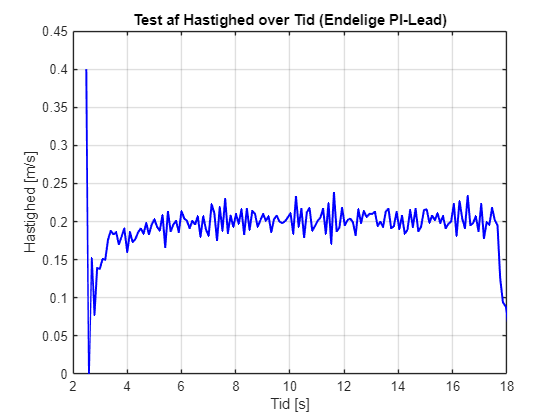

% Plot Velocity Command from full_log15.csv

% Clear workspace and figures
clc; clear; close all;

% Load the CSV file
data = readtable("C:\Users\Markus\Dropbox\Uni\6. Semester\Bachelorprojekt\Bachelorprojekt\No wheel osscilations\full_log15.csv");
data2 = readtable("C:\Users\Markus\Dropbox\Uni\6. Semester\Bachelorprojekt\Bachelorprojekt\No wheel osscilations\control_log15.csv");
data3 = readtable("C:\Users\Markus\Dropbox\Uni\6. Semester\Bachelorprojekt\Bachelorprojekt\wheel osscilations\full_log15.csv");
% Extract time and velocity command
time = data.Time;
velocity_cmd = data.Velocity_cmd;

% Plot the velocity command
figure;
plot(time, velocity_cmd, 'b-', 'LineWidth', 1.5);
xlabel('Tid [s]');
ylabel('Hastighed [m/s]');
title('Test af Hastighed over Tid (Endelige PI-Lead)');
grid on;
xlim([2, 18]);
ylim([0, 0.45]);

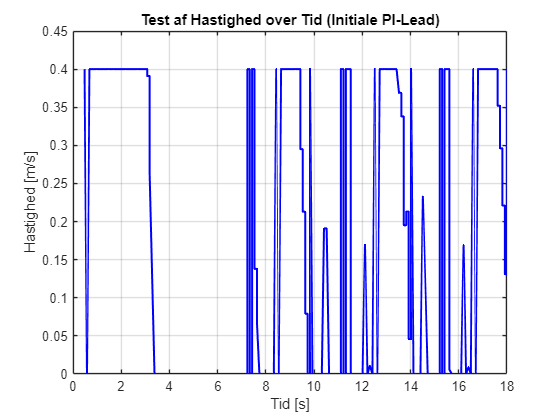



% Plot the velocity command
figure;
plot(data3.Time, data3.Velocity_cmd, 'b-', 'LineWidth', 1.5);
xlabel('Tid [s]');
ylabel('Hastighed [m/s]');
title('Test af Hastighed over Tid (Initiale PI-Lead)');
grid on;

% Set axis limits
xlim([0, 18]);
ylim([0, 0.45]);

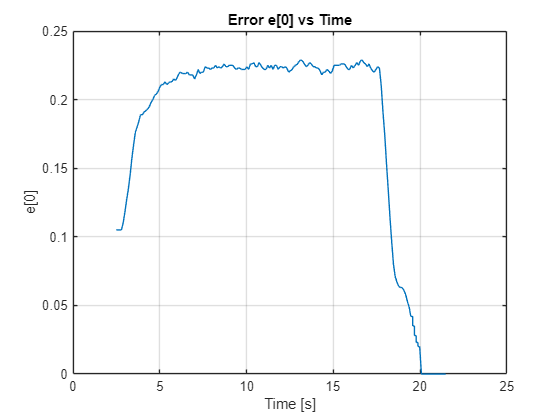


% Declare symbolic variable (if needed for later)
syms z


plot(data2.Time, data2.e0);
xlabel('Time [s]');
ylabel('e[0]');
title('Error e[0] vs Time');
grid on;